### Adaptive Control

Design a minimum variance self-tuning regulator that drives an inverted pendulum represented by the function hw_armax to the desired position (in this case to zero).

First generate u and y parameters from the hw_armax function

n = 500; memoryIN = randn(3,n); u = 10*rand(n,1);
y = zeros(n,1); memoryOUT = zeros(3,n);
for j = 1:n-1
   [y(j+1),memoryOUT(:,j+1)] = hw_armax(u(j+1),memoryIN(:,j+1));
   memoryIN(:,j+1) = memoryOUT(:,j);
end

Then generate the system parameters using the LSE

K = linspace(1,n,n); theta = zeros(4,501); phi = zeros(4,501); P = eye(4);
u_con = zeros(n,1); y_con = zeros(n,1);
for i = 3:499
    phi(:,i) = [y(i-1) y(i-2) u(i-1) u(i-2)]';
    theta(:,i+1) = theta(:,i) + P*phi(:,i)/(1+phi(:,i)'*P*phi(:,i))*( ...
        y(i+1)-phi(:,i)'*theta(:,i));
    P = P - (P*phi(:,i)*phi(:,i)'*P)/(1+phi(:,i)'*P*phi(:,i));
end

Then the minimum variance self-tuning regulator is designed using the parameters from the LSE and the inputs and outputs are plotted.

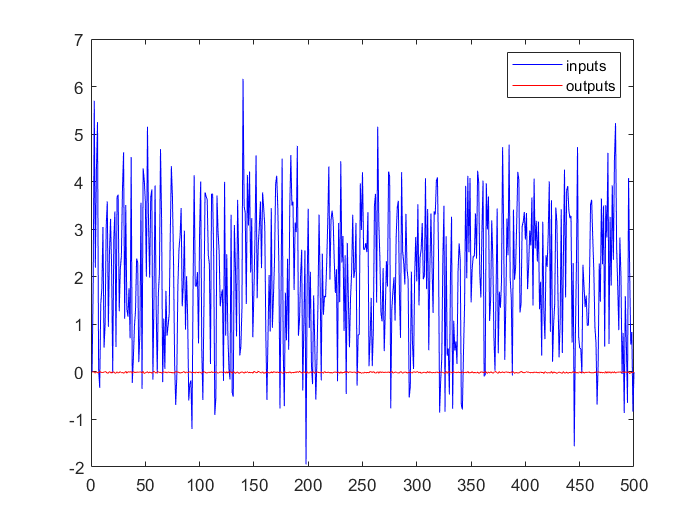

for k = 2:n-1
    u_con(k) = -(1/theta(3,n))*(theta(1,n)*y(k)+theta(2,n)*y(k-1)+theta(4,n)*u(k-1));
    y_con(k+1) = theta(1,n)*y(k) + theta(2,n)*y(k-1) + theta(3,n)*u_con(k) + theta(4,n)*u_con(k-1); 
end
plot(K,u_con,'b',K,y_con,'r')
legend('inputs','outputs')

From the plots above, we can see that the controller keeps varying the inputs to keep the output at zero. 

#### Problem 2 with the LQG-STR

Repeat the problem above but use a linear quadratic gaussian self-tuning regulator (LQG-STR). 

First create the Kalman filter. The system state-space is created from the LSE parameters

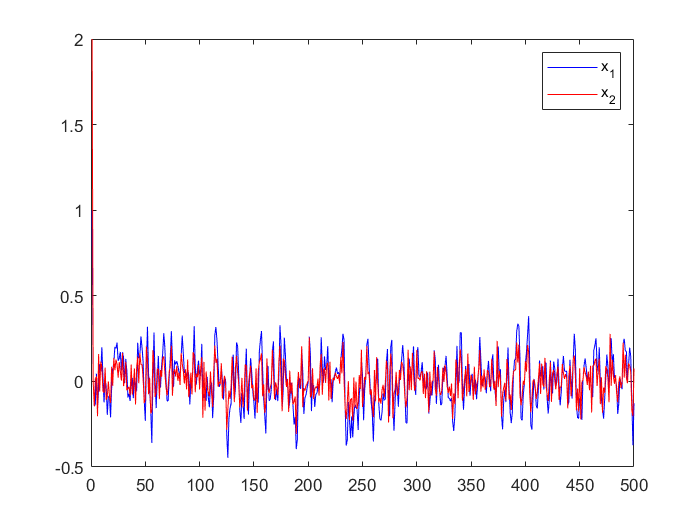

A = [theta(1,500) 1;theta(2,500) 0]; B = [theta(3,500);theta(4,500)]; C= [1 0]; n=500; u_lqg= zeros(n,1); Q = 0.1*randn(n,1); x_ref = [0;0];
x_k = zeros(2,n); E = eye(2); H = y - y_est; R = cov(H); G = [theta(1,500)+1;theta(2,500)];
P = eye(2); T=1; S = P; u = zeros(n,1); x=zeros(2,n); x(:,1) = [1;2]; k = linspace(1,n,n);
for i = 2:n-1
    L = E*C'/(C*E*C'+ R*randn);
    E = A*(eye(2)-L*C)*E*A' + G*0.01*G';
    x_k(:,i)= A*x_k(:,i-1) + L*(y(i) - C*A*x_k(:,i-1));
    K = inv(T + B'*S*B)*B'*S*A;
    S = S + A'*S*B*inv(T+B'*S*B)*B'*S*A;
    u_lqg(i) = -K*(x_k(i)-x_ref);
    x(:,i+1) = A*x(:,i)+B*u_lqg(i) + Q(i);
end
plot(k,x(1,:),'-b',k,x(2,:),'-r')
legend('x_1','x_2')

From the plot above, using an initial condition of (1,2), we can see that the LQG-STR successfully drives the state $x_1 ,\;$which is also the output $\theta ,$ to zero on the very next iteration and keeps it at 0 though with some noise.

### Problem 3

Design a controller so that the angle of the inverted inverted pendulum follows the following reference $r\left(t\right)=A\;\cos \left(\omega t\right)$

First we create a vector of discretized values for the reference over a time period T

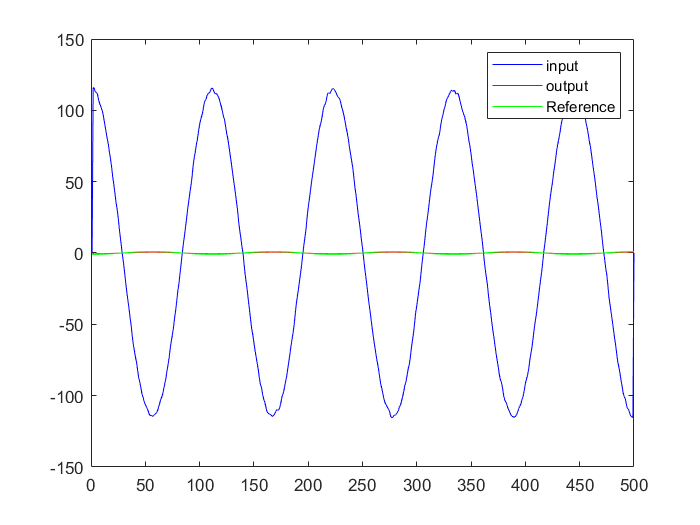

n = 500; t = linspace(1,10,n); A = 1; f = 0.5; r = A*cos(2*pi*f*t); u_con = zeros(n,1); y_con = zeros(n,1);
for l= 2:n-1
    u_con(l) =(r(l)/theta(3,n)) -(1/theta(3,n))*(theta(1,n)*y(l)+theta(2,n)*y(l-1)+theta(4,n)*u(l-1));
    y_con(l+1) = theta(1,n)*y(l) + theta(2,n)*y(l-1) + theta(3,n)*u_con(l) + theta(4,n)*u_con(l-1);
end
plot(k,u_con,'b',k,y_con,'r',k,r,'g')
legend('input','output','Reference')

From the plot above, we can see that the controller successfully gets the output to follow the same trajectory as the reference.